# Bitcrusher

## Dirac signal

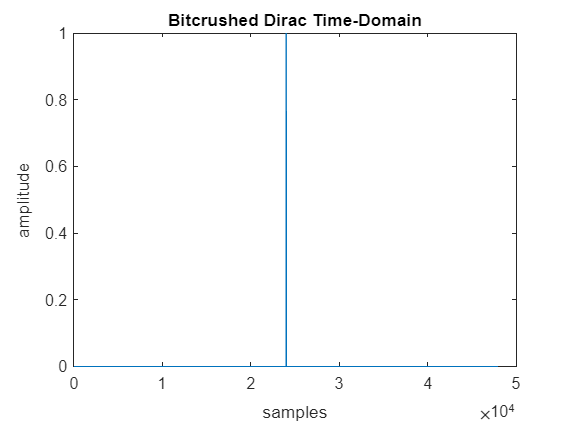

[dirac, fs] = audioread('diracTest.wav');

% Set buffer parameters
buff_length = 480;

% Initialize plugin
bitcrush = BitCrusher();  

% Setting bit crusher parameters
bitcrush.bitDepth = 4; 
bitcrush.normalizedFreq = 1; 

% Set variables for buffering and loop through the test signal
num_buffs = ceil(length(dirac) / buff_length);
dirac_out = zeros(size(dirac));

for b = 1:num_buffs
    start_ind = (b - 1) * buff_length + 1;
    end_ind = min(start_ind + buff_length - 1, length(dirac));
    buff = dirac(start_ind:end_ind, :); 
    processed_buff = process(bitcrush, buff);
    dirac_out(start_ind:end_ind, :) = processed_buff;
end

figure(1);
plot(dirac_out);
title('Bitcrushed Dirac Time-Domain');
xlabel('samples');
ylabel('amplitude');

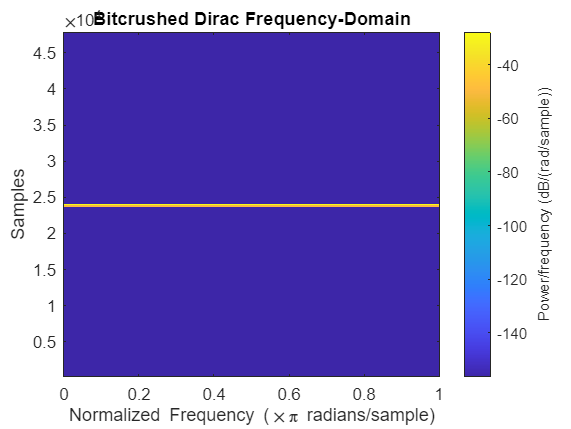



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(2);
spectrogram(dirac_out, hamming(win_length), overlap_length, nfft);
title('Bitcrushed Dirac Frequency-Domain');

## ESS

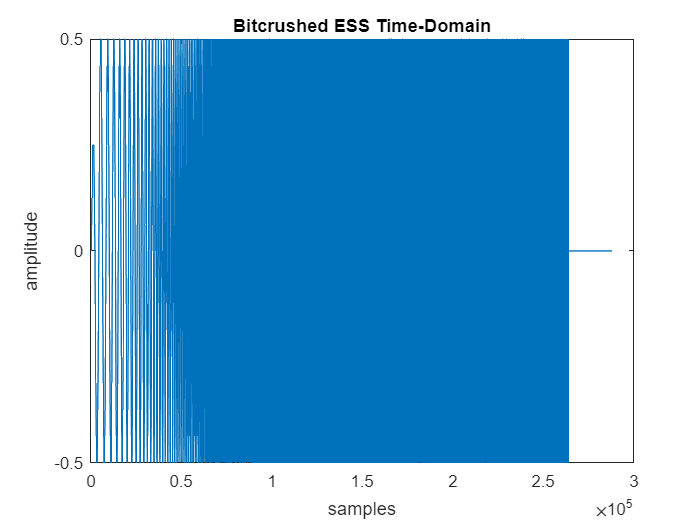

[ess, fs] = audioread('sineSweep.wav');

num_buffs = ceil(length(ess) / buff_length);
ess_out = zeros(size(ess));

for b = 1:num_buffs
    start_ind = (b - 1) * buff_length + 1;
    end_ind = min(start_ind + buff_length - 1, length(ess));
    buff = ess(start_ind:end_ind, :);
    processed_buff = process(bitcrush, buff);
    ess_out(start_ind:end_ind, :) = processed_buff; 
end

figure(3);
plot(ess_out);
title('Bitcrushed ESS Time-Domain');
xlabel('samples');
ylabel('amplitude');

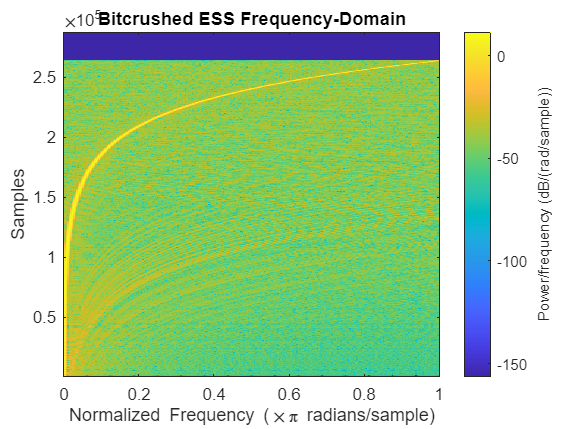



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(4);
spectrogram(ess_out, hamming(win_length), overlap_length, nfft);
title('Bitcrushed ESS Frequency-Domain');

## Pink Noise

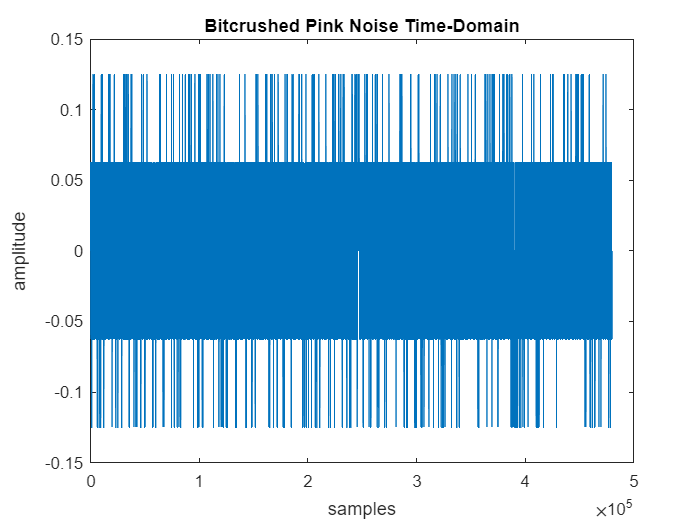

[pink_noise, fs] = audioread('pinkNoise.wav');

num_buffs = ceil(length(pink_noise) / buff_length);
pink_noise_out = zeros(size(pink_noise));


for b = 1:num_buffs
    start_ind = (b - 1) * buff_length + 1;
    end_ind = min(start_ind + buff_length - 1, length(pink_noise));
    buff = pink_noise(start_ind:end_ind, :);
    processed_buff = process(bitcrush, buff);
    pink_noise_out(start_ind:end_ind, :) = processed_buff;
end

figure(5);
plot(pink_noise_out);
title('Bitcrushed Pink Noise Time-Domain');
xlabel('samples');
ylabel('amplitude');

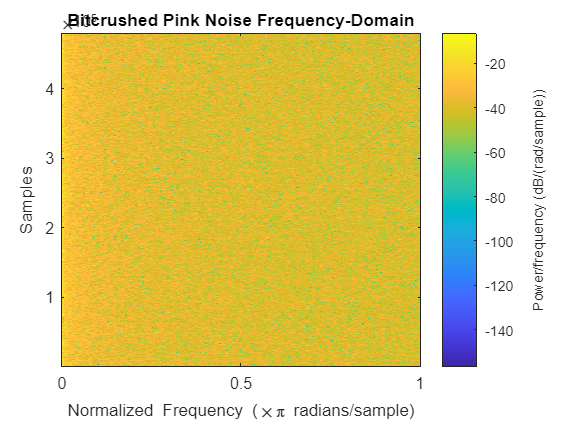



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));
figure(6);
spectrogram(pink_noise_out, hamming(win_length), overlap_length, nfft);
title('Bitcrushed Pink Noise Frequency-Domain');